**Question: How long will a flu outbreak in the future last?**

This question involves prediction. We can not see into the future, thus we have to use data from the past in order to make an educated guess. 

**Defining the Model**

The bases of our model involves stocks and flows. A stock is a collection of "stuff," and a flow, is a means for "stuff," to flow from one stock to another. In this case, our stocks are susceptible, infectious, and recovered. Our flows are from susceptible to infectious, infectious to recovered, and recovered to susceptible. A visual representation of the stocks and flows can be seen below. 

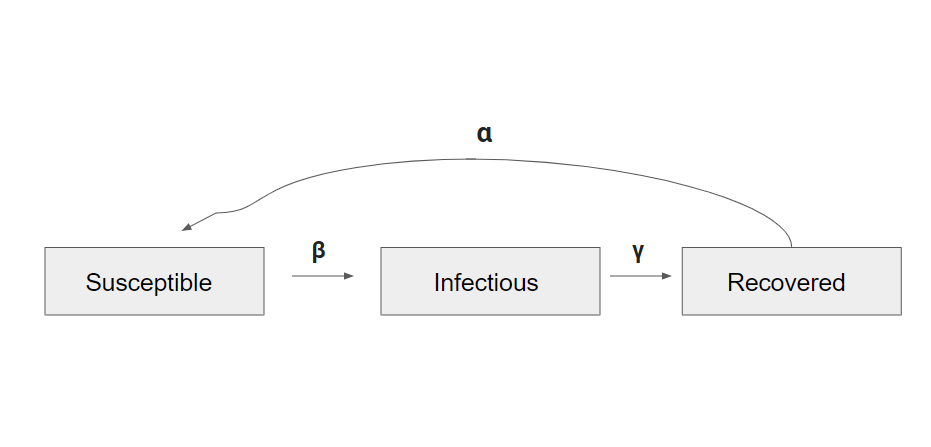

The equations listed below can help define our model. Listed below is also an explanation of the variables used in the equation


$$S_t = \text{Count of Susceptible persons at time } t \\
I_t = \text{Count of Infectious persons at time } t \\
R_t = \text{Count of Recovered persons at time } t $$



$$\Delta I_t = \text{Number of Infections at time } t \\
\Delta R_t = \text{Number of Recoveries at time } t\\
\Delta S_t = \text{Number of Resusceptiblities at time } t$$



$$S_{t+1} = S_t - \Delta I_t+\Delta S_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t\\
R_{t+1} = R_t + \Delta R_t-\Delta S_t $$


In addition, $\Delta R_t = \gamma \times I_t$  , $\Delta I_t = \beta \times I_t \times S_t$ , and$\Delta S_t = \alpha \times R_t $.

**Defining Initial State**

First, we defined our initial state, and gave a guess of what suitable beta, gamma, and alpha values may be. 


% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 45;
gamma = 1/4;
alpha = 1/30;
num_week = 40;

**Running Our Simulation.**

Then, we ran our simulation for 40 weeks, and plotted the number of susceptible, infected, and recovered individuals per week.

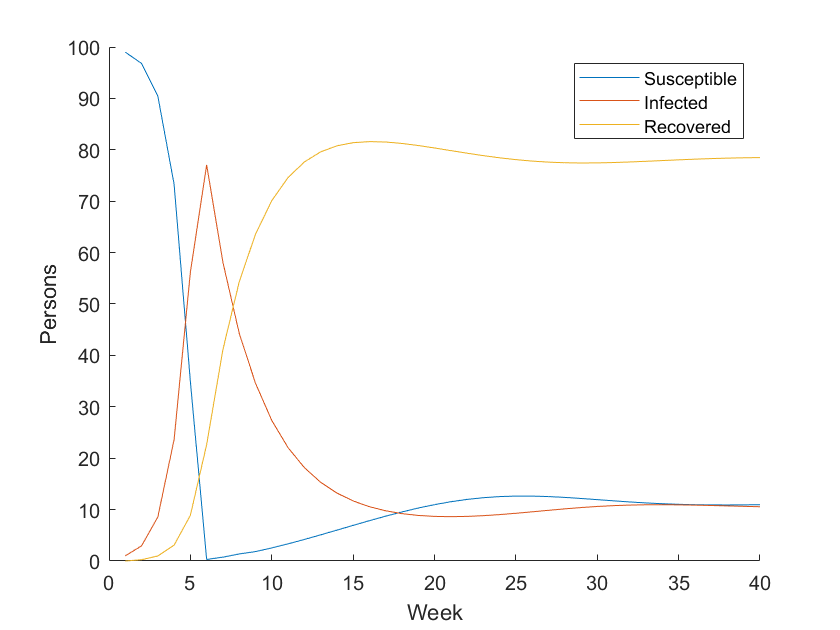


% Run simulation
[S, I, R, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
%(s, i, r, beta, r_time, s_time, infected_list, step)
hold off;

**Fitting Our Data**

Next, we fitted our data by comparing our simulated graph to a past outbreak. We then changed parameters around, until our model fit. 

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


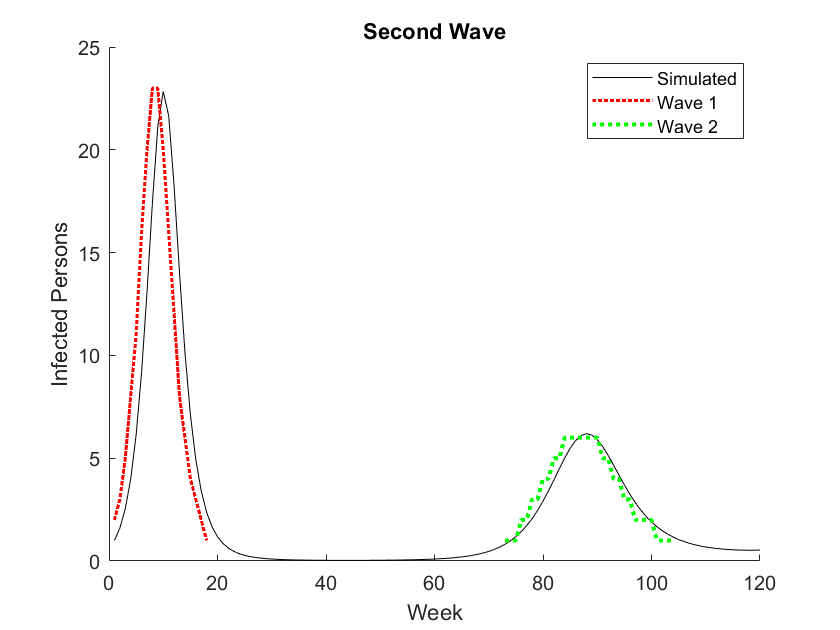


% Configure the simulation

s_0 = 99;
i_0 = 1;
r_0 = 0;
beta = 1 / 90;
gamma = 1/2;
alpha = 1/60;
num_week = 120;

% Run simulation
[S_fit, I_fit, R_fit, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W, I_fit, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

By playing around with the numbers, we found that the best fit was when beta = 1/90, gamma = 1/2,  and alpha = 1/60.

**Verification**

Next, we had to verify our model. To do this, we made sure that the total number of people would always equal zero. 

% TODO: Compute total persons, plot
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....
total = S_fit + I_fit + R_fit

total =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000




[S_fit, I_fit, R_fit, W_fit, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(W_fit, total, 'k-'); label2 = "Total Persons";

xlabel("Week")
ylabel("Total Persons")
legend({label1, label2})

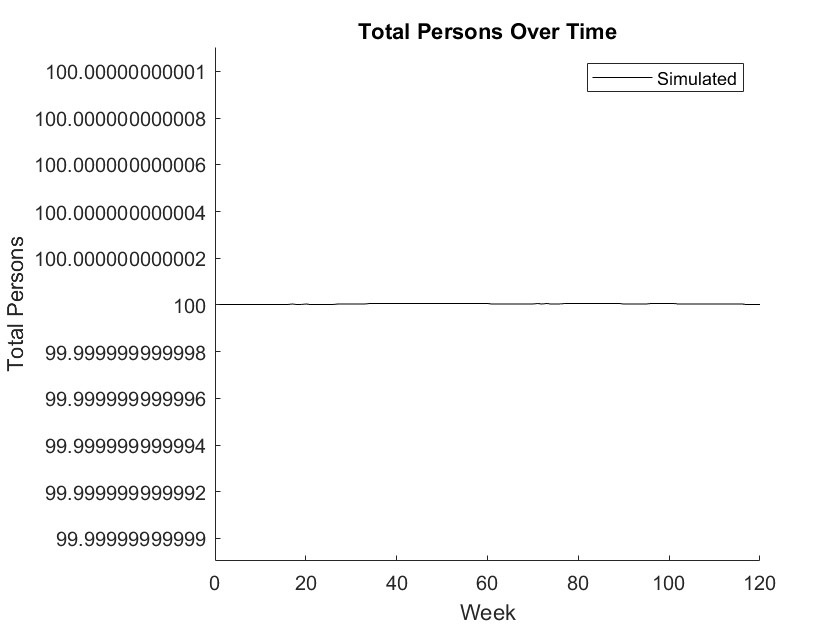

title("Total Persons Over Time")

**Sweeping Parameters**

To visualize how our model changes, we swept all of the parameters involving the flow. We did this by keeping two parameters constant (consistent with our fitted data), and then plotting how infections changed with the other changing parameter. 

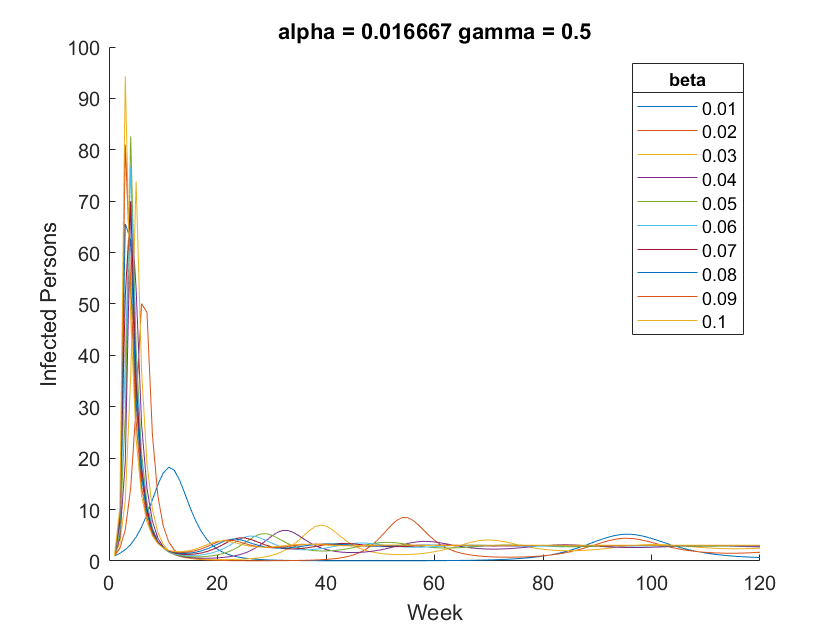

%run beta_sweep
beta_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

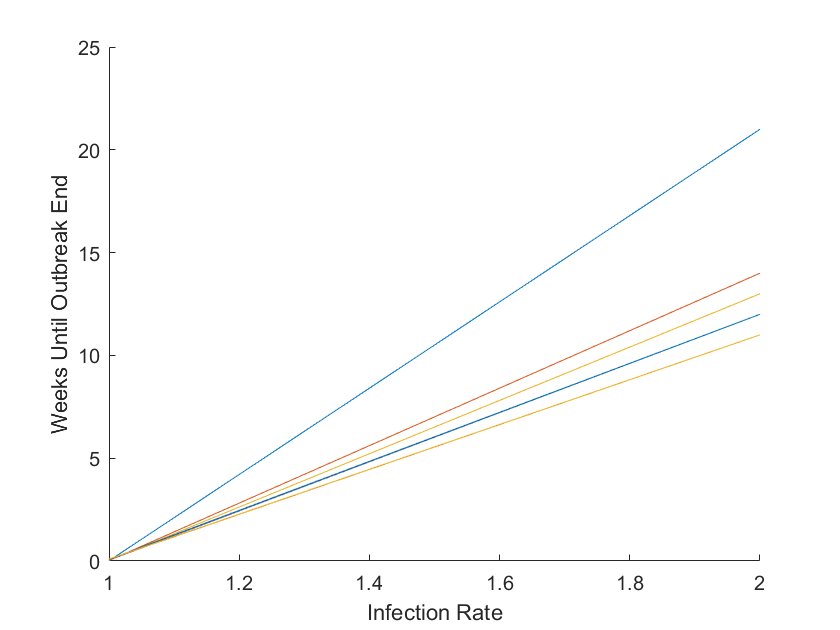

ans =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000
   21.0000   14.0000   13.0000   12.0000   12.0000   12.0000   12.0000   12.0000   11.0000   11.0000


beta_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week);

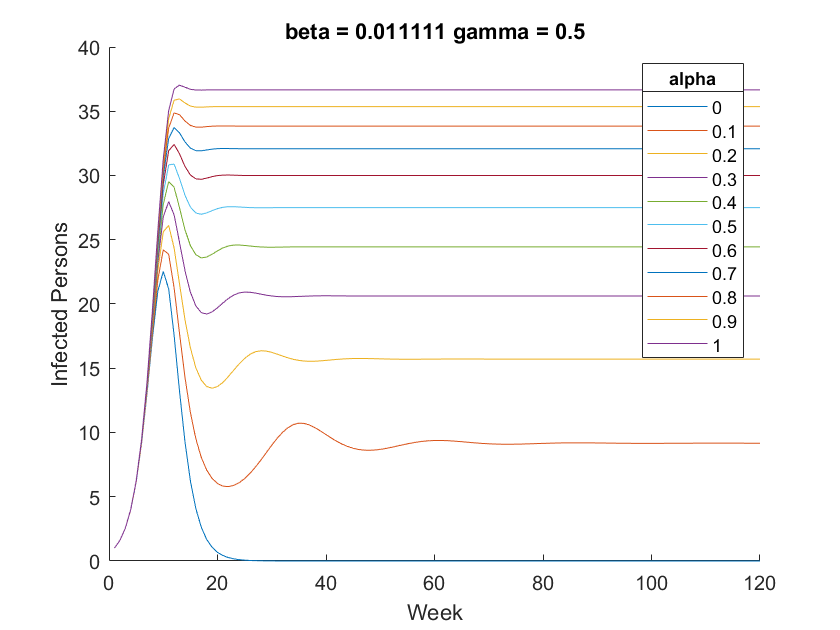

alpha_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

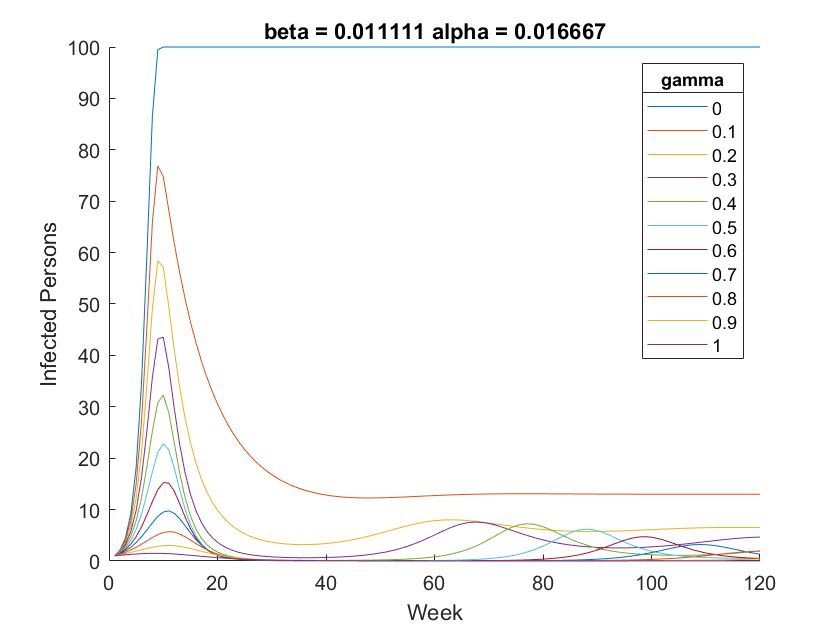

gamma_sweep(s_0, i_0, r_0, beta, gamma, alpha, num_week);

**Results**

Next, we found out when the outbreak would end for our fitted data. To do this, we defined the end of the outbreak as when the slope first equaled around zero (less than one), excluding the peak. 

s_0 = 99;
i_0 = 1;
r_0 = 0;
beta = 1 / 90;
gamma = 1/2;
alpha = 1/60;
num_week = 120;

% Run simulation
[S_fit, I_fit, R_fit, W, w] = simulation(s_0, i_0, r_0, beta, gamma, alpha, num_week);


[w] = end_check(I_fit);
end_I = I_fit(w);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W, I_fit, 'k-'); label1 = "Simulated";
plot(w,end_I,'ro'); label2 = "outbreak_ end"

label2 = "outbreak_ end"

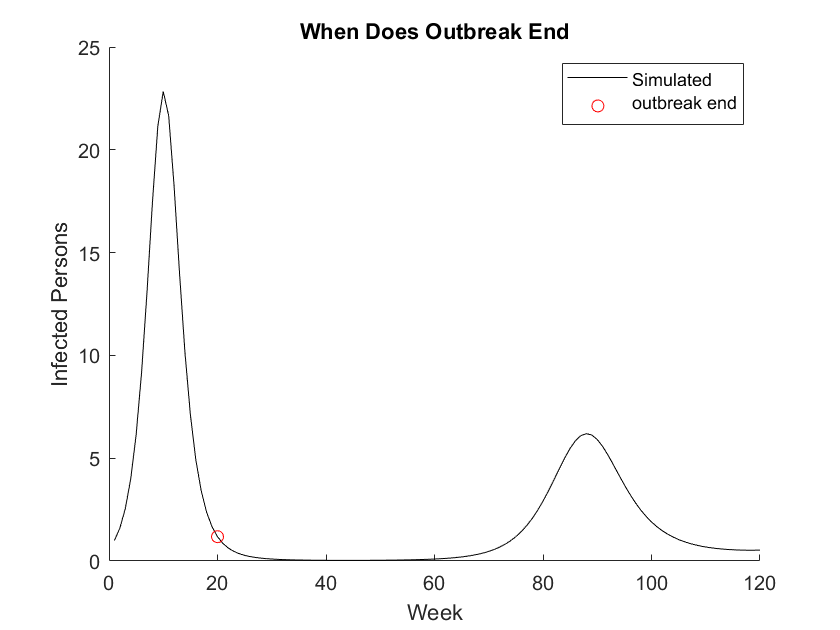


xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("When Does Outbreak End")


end_text = 'outbreak ends at week'

end_text = 'outbreak ends at week'

disp(end_text)

outbreak ends at week


disp(w)

    20



From our results, we can conclude that based on our fitted data, the outbreak ends at week 20. 

**Comparison**

If we change how infectious the disease is we see how our results would change. 

ans =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000
   21.0000   14.0000   13.0000   12.0000   12.0000   12.0000   12.0000   12.0000   11.0000   11.0000


beta_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)

gamma_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)
alpha_sweep_end(s_0, i_0, r_0, beta, gamma, alpha, num_week)

**Results**

From our results, we can conclude that based on our fitted data, the outbreak ends at week 20. However, if other factors change it could effect how long the outbreak is

**Interpretation**